# Navigate a mobile robot using PRM

Copyright (C) 1993-2018, by Peter I. Corke, http://www.petercorke.com

Our robot will operate within a grid world that contains free space where it can drive and obstacles.  We load a map of the world

load map1

% which loads a variable called map

about map

map [double] : 100x100 (80.0 kB)


and the cells contain zero if it is free space (driveable) and one if it is an obstacle.

Now we create an instance of a robot with the PRM navigation algorithm

prm = PRM(map);


and because PRM is a probabilistic method we will reset the random number generator to a known state

randinit

Now we define the goal and start coordinates

goal = [50,30];
start = [20, 10];

then ask the robot to plan a path to goal (it will take few seconds)

prm.plan();

The roadmap planner does not need to know, yet, the goal or start positions, it chooses random points in the world and tries to find obstacle-free paths between them (like railway lines or freeways)

Now we can display the obstacles and the cost to reach the goal from every point in the world

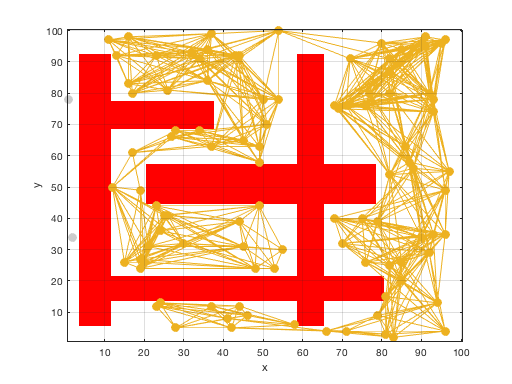

prm.plot();

Now we can find a path from start to goal using the roadmap 

p = prm.query(start, goal);

and now display it

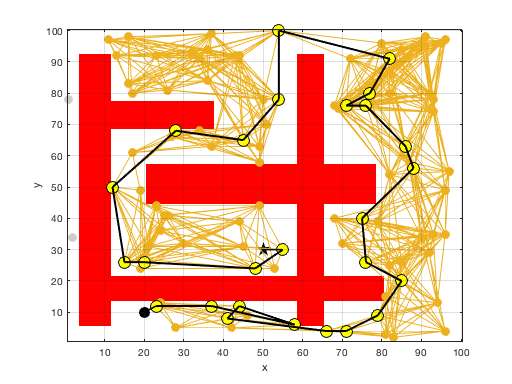

prm.plot(p);